clear, clc

## Setup

Assume it's a 2D problem x positive to the right and z positive up

% Constants
g = 9.8;    % gravity
m = 1;      % mass
J = 5e-2;    % moment of inertia

% Assume the trajectory is a circle with radius:
r = 1;
% and x and z zero at the bottom of the circle

## Minimum start velocity

The drone starts with an initial velocity towards the right. The minimum velocity is that which gives the drone enough energy to reach the top of the loop (zero thrust at the top). So at the top the centripetal force is just the weight.

Centripetal force is calculated as F = m*v^2/r. Solving: v = sqrt(m*g*r/m) = sqrt(g*r)

min_speed_top = sqrt(g*r)

min_speed_top = 3.1305

Assuming no drag, energy is conserved. The energy at the top is the kinetic energy (rotational and linear) plus the potential energy

KE_r = 1/2*J*omega^2

KE_l = 1/2*m*v^2

PE = m*g*h

min_omega_top = min_speed_top/r;
min_KE_r_top = 0.5*J*min_omega_top^2;
min_KE_l_top = 0.5*m*min_speed_top^2;
PE_top = m*g*(2*r);
min_E = min_KE_r_top + min_KE_l_top + PE_top;

At the bottom, the potential energy is zero so min_E = min_KE_r_bottom + min_KE_l_bottom = 0.5*J*min_omega_bottom^2 + 0.5*m*min_speed_bottom^2 = 0.5*J*min_speed_bottom^2/r^2 + 0.5*m*min_speed_bottom^2 = 0.5*(J/r^2 + m)*min_speed_bottom^2. Solving:

min_speed_bottom = sqrt(2*min_E/(J/r^2+m))

min_speed_bottom = 6.8654

## Finding thrust and torque

Let's say the start velocity is then something larger than that

s0 = min_speed_bottom + 0.1;
% the energy is then
E = 0.5*m*s0^2;

It would be nice to write the speed as a function of z so that from that we can compute the time vector.

For this we can continue to use conservation of energy. E = KE_r + KE_l + PE = 0.5*(J/r^2+m)*speed^2 + m*g*z.

Solving: speed = sqrt(2*(E-m*g*z)/(J/r^2+m))

Let's make a z vector and compute the speed and omega

z_raw = linspace(0,2*r,1000);
speed_raw = sqrt(2*(E-m*g*z_raw)/((J/r^2)+m));
omega_raw = speed_raw/r;

Energy = m*g*z_raw + 0.5 * ((J/r^2)) .* omega_raw.^2 + 0.5 * m * speed_raw.^2;  

From omega and z we can compute the time vector because we know that z = r - r*cos(omega*t) 

t_raw = acos((r - z_raw)/r)./omega_raw;

Let's now compoute a time vector with constant dt's

t = linspace(0,t_raw(end),1000);
omega = interp1(t_raw,omega_raw,t);

And complete the other half of the circle

t = [t,t(2:end)+t(end)];
omega = [omega,flip(omega(1:end-1))];
x = r * sin(omega .*t); %r*sin(-omega.*t);
z = r * cos(omega .* t); %r*(1-cos(omega.*t));

Now let's plot x and z

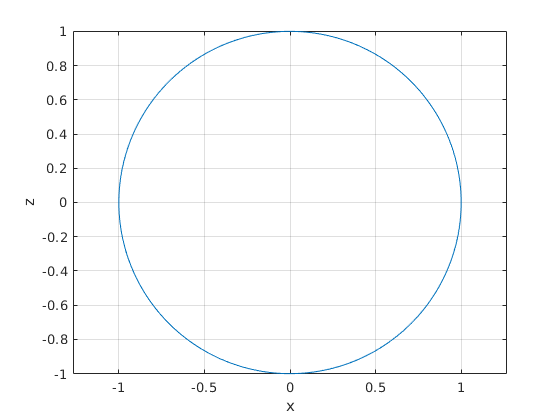

figure(1)
plot(x,z)
axis equal
grid on
xlabel('x'); ylabel('z')

We can now compute the thrust vector because it's equal to the centripetal force

thrust = m*r*omega.^2;

And the pitch torque:

alpha = diff(omega)./diff(t);
tau = J*alpha;

Let's plot the two

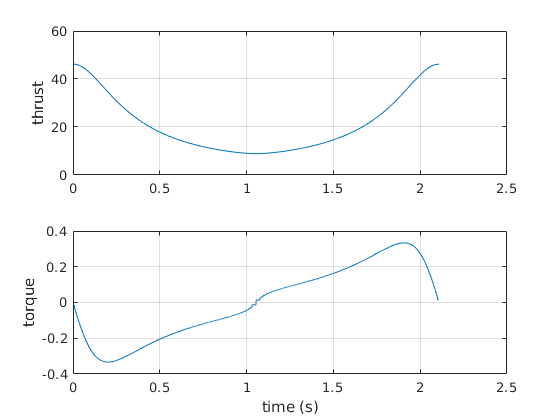

figure(2)
subplot(2,1,1)
plot(t,thrust)
ylabel('thrust')
grid on
subplot(2,1,2)
plot(t(1:end-1),tau)
ylabel('torque')
xlabel('time (s)')
grid on

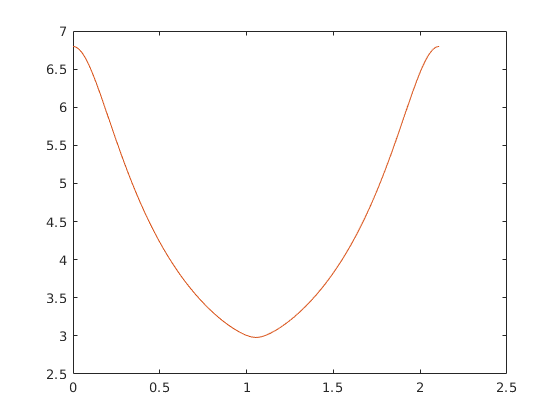

figure(3)
plot(t_raw, speed_raw); hold on;
plot(t, omega);